imshow("map1.png")
hold on
[xi,yi] = getpts();
Path = [xi yi];
%Path = [1 1;2 2;3.2 5; 3.5 5.5;4 6; 7 5; 7 8];
M_k = [1 / 6, 4 / 6, 1 / 6, 0;
    -3 / 6, 0, 3 / 6, 0;
    3 / 6, -6 / 6, 3 / 6, 0;
    -1 / 6, 3 / 6, -3 / 6, 1 / 6 ];
A = M_k(1,:);
for i = 2:size(Path,1)
    B = A(end,:);
    A = [A,zeros(i - 1,1)];
    A = [A;0,B];
end
A = [A;zeros(1,size(Path,1) - 1),M_k(2,:)];
A = [A;zeros(1,size(Path,1)),M_k(2,1:end-1)];
A = [A;M_k(2,:),zeros(1,size(Path,1) - 1)];
b = [Path;0,0;0 0;0 0];
BsplineControlPoint = A\b;


OptimizedControlPos = BsplineControlPoint;
for p = 4:size(BsplineControlPoint,1) - 4
    OptimizedControlPos(p,:) =OptimizedControlPos(p,:) + (BsplineControlPoint(p - 1,:) - BsplineControlPoint(p,:)) * 0.2  + (BsplineControlPoint(p + 1,:) - BsplineControlPoint(p,:)) * 0.2 ;
end

TimeLine = rand(1,size(Path,1) + 5)*1 + 0.5;
TimeLine(1) = -2;
TimeLine(2) = -1;
TimeLine(3) = 0;
TimeLine(4) = 1;
TimeLine(5) = 2;
TimeLine(6) = 3;
for k = 7:(size(Path,1))
    TimeLine(k) = TimeLine(k) + TimeLine(k - 1);
end
for k = (size(Path,1)): (size(Path,1)+5)
    TimeLine(k) = 1 + TimeLine(k - 1);
end
TimeLine

TimeLine =    -2.0000   -1.0000         0    1.0000    2.0000    3.0000    3.8063    4.8149    5.8256    6.8256    7.8256    8.8256    9.8256   10.8256   11.8256


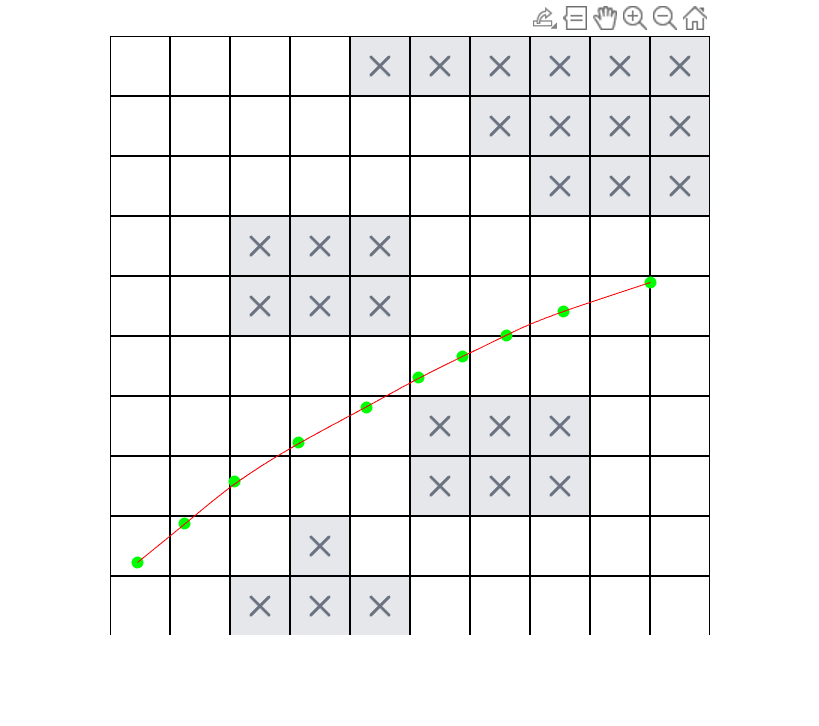


scatter(Path(:,1),Path(:,2),"filled",'g')
hold on
[x, y] = GetTrajectoryWithTimeLine( OptimizedControlPos,TimeLine);
plot(x,y,'b')
hold on

[x1, y1] = GetTrajectoryForNUB( OptimizedControlPos,TimeLine);
plot(x1,y1,'r')

hold off

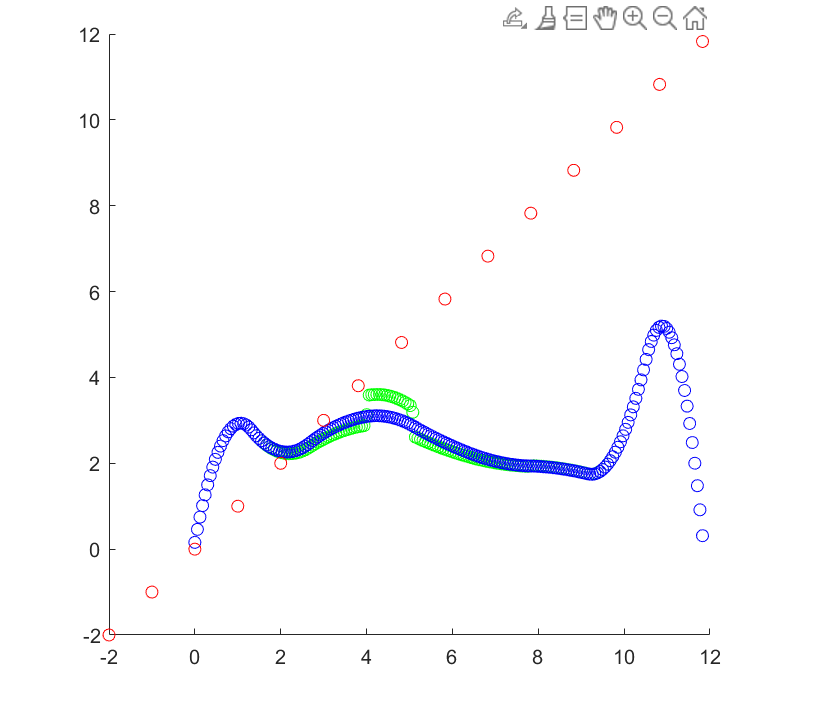


ts = linspace(0,TimeLine(end) ,size(x,2)-1);
scatter(ts,diff(x ),'g');
hold on
ts = linspace(0,TimeLine(end) ,size(x1,2)-1);
scatter(ts,diff(x1 ),'b');
scatter(TimeLine,TimeLine,'r');